fontSize = 20;
R=16;
minAllowableDistance = 1;
requiredNumberOfPoints = 20;
pointCount = 0;
for k = 1 : 100 * requiredNumberOfPoints
	thisTheta = 2*pi*rand();
	thisRadius = R * rand();
	% Compute distances to other points.
	thisx = thisRadius .* cos(thisTheta);
	thisy = thisRadius .* sin(thisTheta);
	if k == 1
		% We can ALWAYS place/accept the first point.
		pointCount = pointCount + 1; % Increment count.
		x(pointCount) = thisx;
		y(pointCount) = thisy;
	else
		% Compute distances to other points
		theseDistances = sqrt((x-thisx) .^ 2 + (y - thisy) .^ 2);
		if min(theseDistances) >= minAllowableDistance
			pointCount = pointCount + 1; % Increment count.
			% We can ALWAYS place/accept the first point.
			x(pointCount) = thisx;
			y(pointCount) = thisy;
			distances(pointCount) = min(theseDistances);
			% Bail out if we have enough points.
			if pointCount >= requiredNumberOfPoints
				break;
			end
		end
	end
end
fprintf('Placed %d points after %d attempts.\n', pointCount, k);

Placed 20 points after 24 attempts.


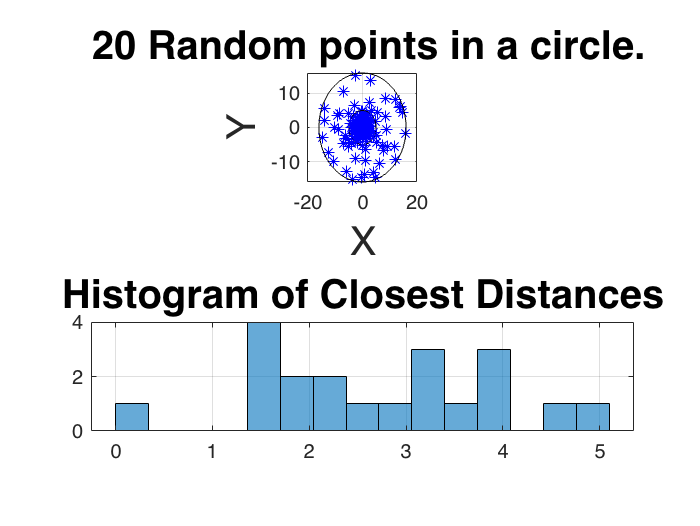

% Plot points.
subplot(2, 1, 1);
plot(x, y, 'b*')
xlim([-R, R]);
ylim([-R, R]);
axis('equal', 'square');
grid on;
hold on;
% Plot circle
pos = [-R, -R, 2*R, 2*R]; 
rectangle('Position',pos,'Curvature',[1 1])
xlabel('X', 'fontSize', fontSize);
ylabel('Y', 'fontSize', fontSize);
caption = sprintf(' %d Random points in a circle.', requiredNumberOfPoints);
title(caption, 'fontSize', fontSize);
% Plot histogram of distances.
subplot(2, 1, 2);
histogram(distances, 15);
grid on;
title('Histogram of Closest Distances', 'fontSize', fontSize);

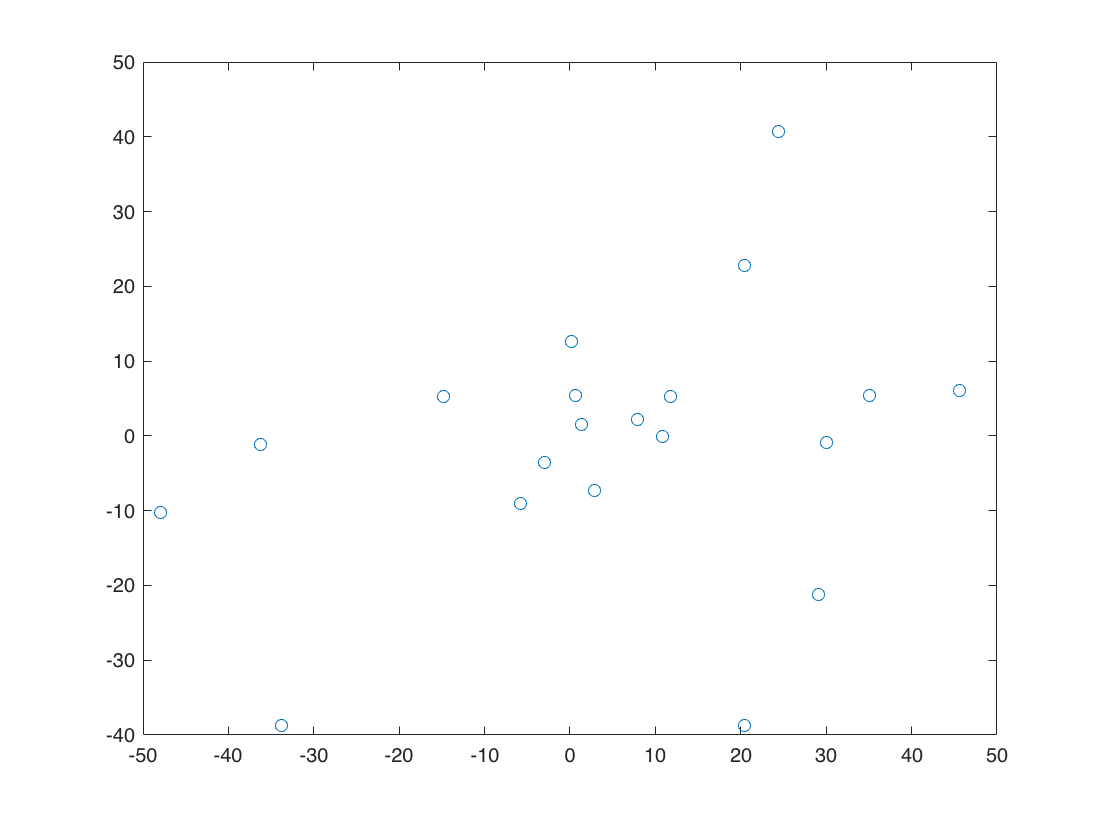


nWant=20;
R1=16;

MinDist1=3;
X1       = zeros(1,nWant/2);
Y1       = zeros(1,nWant/2);
dist_2_1  = MinDist1 ^ 2;      

R2=32;

MinDist2=6;
X2       = zeros(1,nWant/2);
Y2       = zeros(1,nWant/2);
dist_2_2  = MinDist2 ^ 2;
iLoop   = 1;                % Security break to yoid infinite loop
nValid  = 0;
while nValid < nWant/2 && iLoop < 1e6
  newX1 = (R1) * (rand).*cos(2*pi*rand);
  newY1 = (R1) * (rand).*sin(2*pi*rand);
  if all(((X1(1:nValid) - newX1).^2 + (Y1(1:nValid) - newY1).^2) >= dist_2_1)
    % Success: The new point does not touch existing points:
    nValid    = nValid + 1;  % Append this point
    X1(nValid) = newX1;
    Y1(nValid) = newY1;
  end
  iLoop = iLoop + 1;
end
%r = a + (b-a).*rand(N,1)
nValid1=0;
iLoop1=1;
while nValid1 < nWant/2 && iLoop1 < 1e6
% r = a + (b-a).*rand(N,1).
    newX2 =(R1+randi([R1 R2])).*cos(2*pi*rand);
    newY2 =(R1+randi([R1 R2])).*sin(2*pi*rand);
%      newX2=sqrt((R2-5)^2+(R2^2-(R2-5)^2)*rand+R1).*cos(2*pi*rand);
%      newY2=sqrt((R2-5)^2+(R2^2-(R2-5)^2)*rand+R1).*sin(2*pi*rand);
  if all(((X2(1:nValid1) - newX2).^2 + (Y2(1:nValid1) - newY2).^2) >= dist_2_2)...
          && newX2^2+newY2^2>=R1^2
    % Success: The new point does not touch existing points:
    nValid1    = nValid1 + 1;  % Append this point
    X2(nValid1) = newX2;
    Y2(nValid1) = newY2;
  end
  iLoop1 = iLoop1 + 1;
end
X=[X1,X2];
Y=[Y1,Y2];
figure
plot(X,Y,'o')

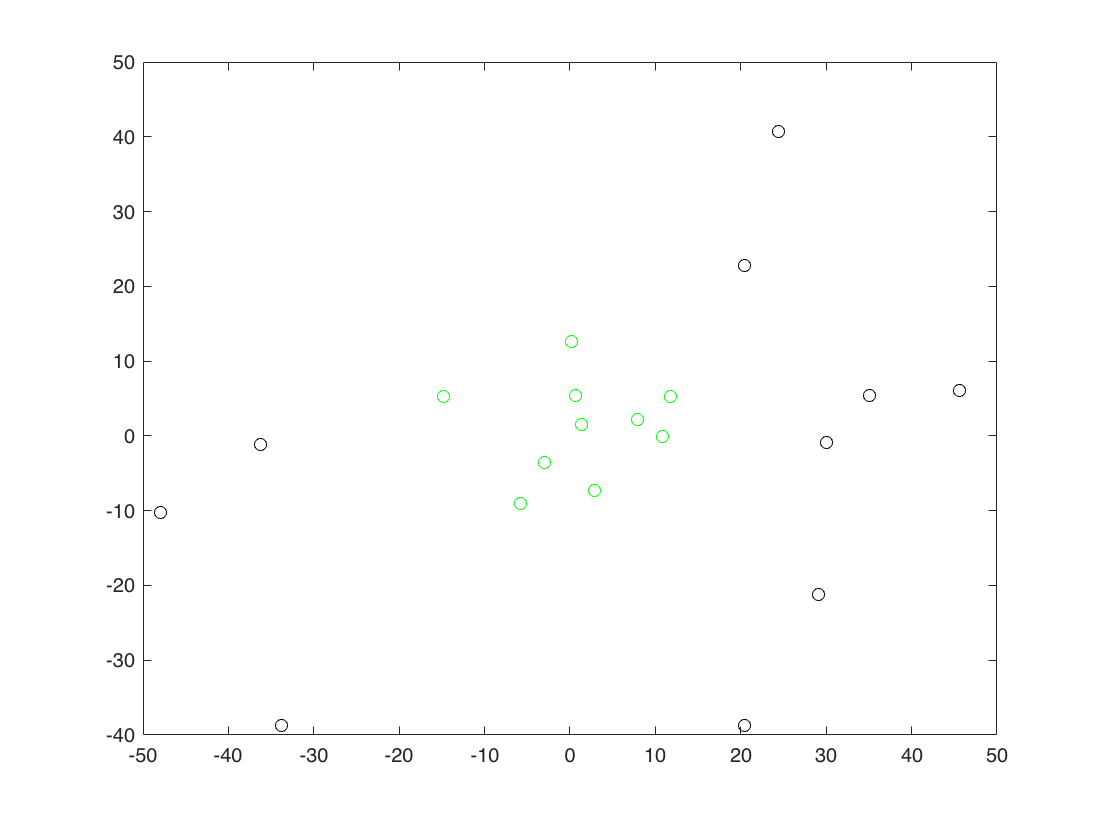

figure
plot(X1,Y1,'go',X2,Y2,'ko')

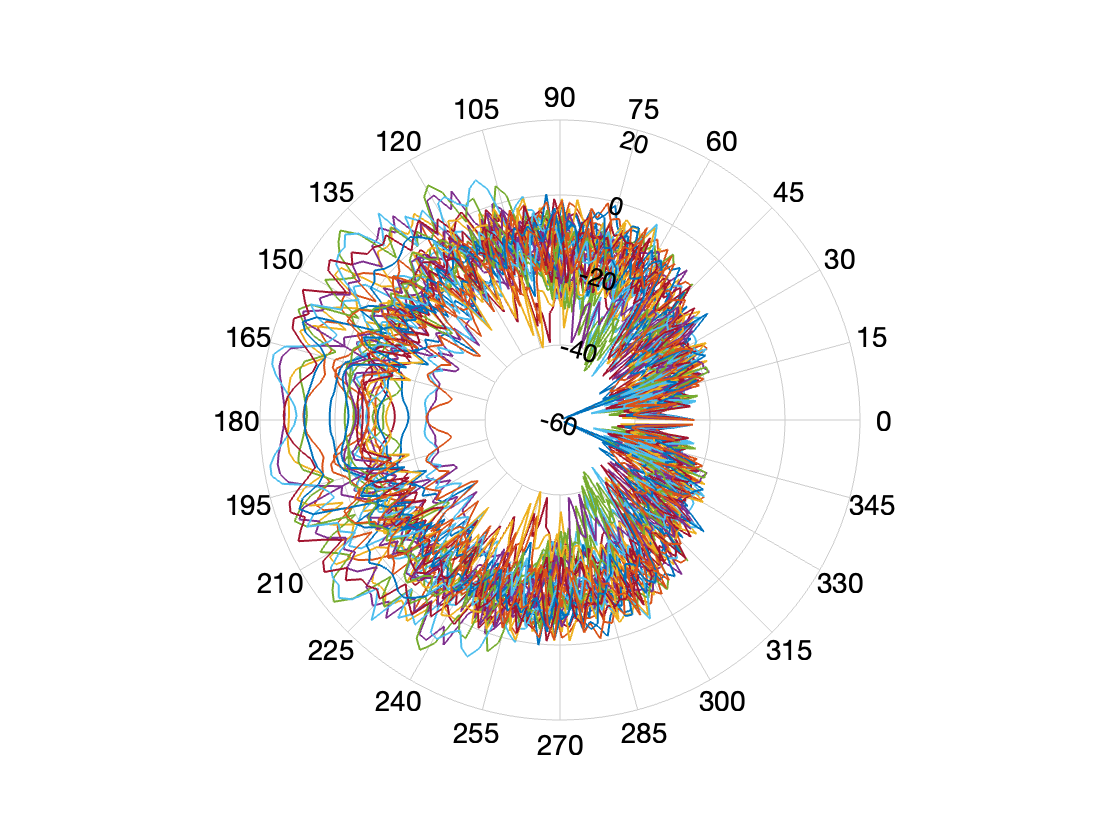

elempos =[X;Y;zeros(1,20)];
data_pseudoarray;



arbitrary = phased.ConformalArray(...
'ElementPosition', elempos,...
'ElementNormal', [0;0] ,...
'Element',ant);

V=pattern(arbitrary,fc,[-180:10:180],[-90:1:90],'PropagationSpeed',c, ...
'CoordinateSystem','polar','Type','directivity');
p=polarpattern(V);

L=findLobes(p);
MainLobe = L.mainLobe

MainLobe = struct with fields:
        index: 111
    magnitude: -1.1974
        angle: 218.7845
       extent: [108 113]


SideLobe = L.sideLobes

SideLobe = struct with fields:
        index: 71
    magnitude: -1.2374
        angle: 139.2265
       extent: [41×2 double]


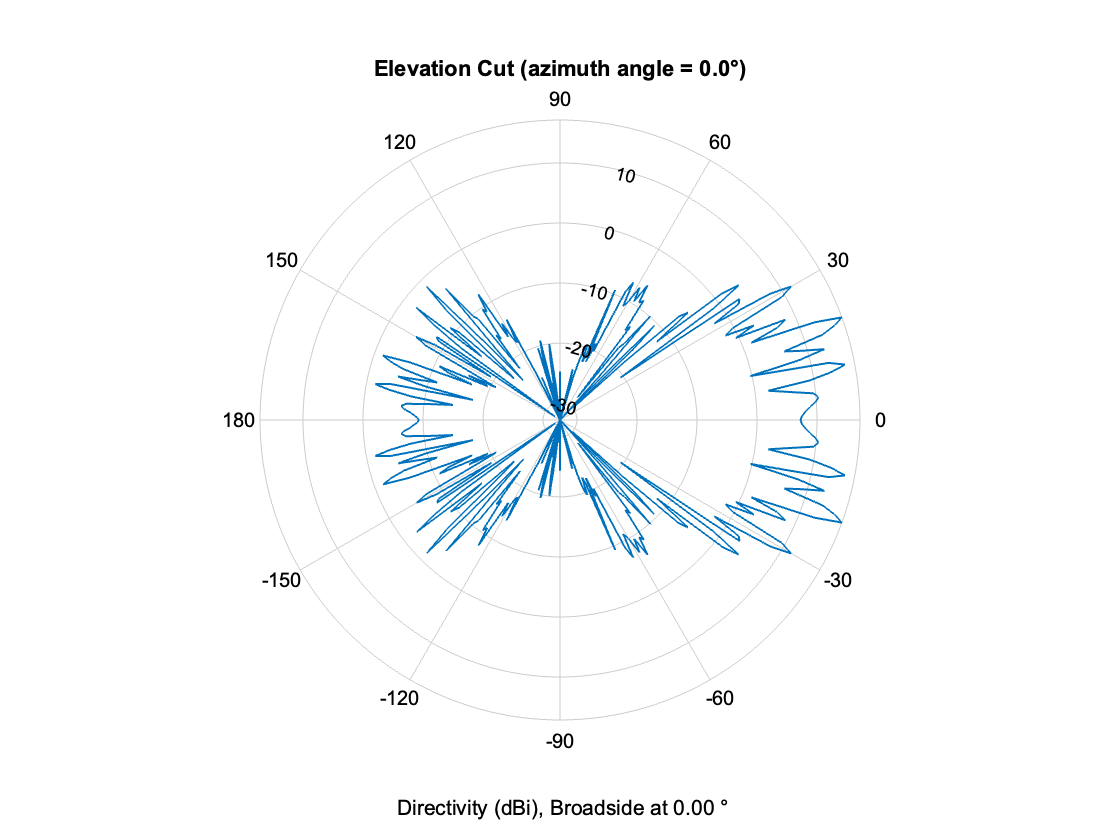

patternElevation(arbitrary,fc,0,'PropagationSpeed',c,...
    'Type','directivity')